## Q1 - part a

clear; clc;

### Load Data

Load the data and split them into estimation and validation datasets.

load q1_402123100.mat

u_val = u(length(u)/2+1:end);
v_val = v(length(u)/2+1:end);
z_val = z(length(u)/2+1:end);
y_val = y(length(u)/2+1:end);

u = u(1:length(u)/2);
v = v(1:length(v)/2);
z = z(1:length(z)/2);
y = y(1:length(y)/2);


%%


Ts = 0.1; 
t = 0:Ts:length(u)*Ts-Ts;
N = length(y);
%%

### Run for Estimation through Loop

fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 5;

for degree=1:1:100
    na = degree;
    nb = degree;
    p = na+nb+1;

    U = arx_U_builder_3(u,y,na,nb,1);
    theta_hat = inv(U'*U)*U'*y;

    y_hat = form_tf_lsim_2(theta_hat, u, t, na, Ts);

    [r2_arx, mse_arx] = rSQR(y, y_hat);

    error = y - y_hat;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end
    
    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);

    covariance = variance*inv(U'*U);
    cov = trace(covariance)/p;
    covs = [covs; cov];
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_arx, mse_arx, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_arx];
    MSEs = [MSEs; mse_arx];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
end

>>> Degree = 1 : R2=-0.013109 | MSE=4.257591 | var=4.283291 | s_hat=2128.795577 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=-0.002442 | MSE=4.212763 | var=4.255316 | s_hat=2106.381374 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.037217 | MSE=4.046094 | var=4.103544 | s_hat=2023.047184 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.060495 | MSE=3.948270 | var=4.020641 | s_hat=1974.134836 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.044131 | MSE=4.017040 | var=4.107403 | s_hat=2008.520016 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.100162 | MSE=3.781568 | var=3.882513 | s_hat=1890.784068 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.092951 | MSE=3.811872 | var=3.929764 | s_hat=1905.935767 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.149934 | MSE=3.572401 | var=3.698137 | s_hat=1786.200255 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.259092 | MSE=3.113667 | var=3.236660 | s_hat=1556.833659 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.344388 | MSE=2.755211 | var=2.876003 | s_hat=1377.605414 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.445626 | MSE=2.329757 | var=2.442093 | s_hat=1164.878454 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.519301 | MSE=2.020136 | var=2.126459 | s_hat=1010.068101 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.557457 | MSE=1.859788 | var=1.965949 | s_hat=929.893821 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.604787 | MSE=1.660884 | var=1.763147 | s_hat=830.442056 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.653406 | MSE=1.456559 | var=1.552835 | s_hat=728.279691 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.705157 | MSE=1.239080 | var=1.326638 | s_hat=619.539788 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.718145 | MSE=1.184494 | var=1.273649 | s_hat=592.246907 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.737369 | MSE=1.103705 | var=1.191906 | s_hat=551.852472 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.742338 | MSE=1.082824 | var=1.174429 | s_hat=541.411830 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.754741 | MSE=1.030702 | var=1.122769 | s_hat=515.350842 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.757138 | MSE=1.020626 | var=1.116659 | s_hat=510.313160 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.763412 | MSE=0.994261 | var=1.092594 | s_hat=497.130462 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.768461 | MSE=0.973042 | var=1.073998 | s_hat=486.521067 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.771023 | MSE=0.962278 | var=1.066827 | s_hat=481.138922 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.773173 | MSE=0.953242 | var=1.061517 | s_hat=476.621120 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.773585 | MSE=0.951511 | var=1.064329 | s_hat=475.755257 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.776436 | MSE=0.939529 | var=1.055650 | s_hat=469.764257 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.778222 | MSE=0.932024 | var=1.051946 | s_hat=466.012085 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.777561 | MSE=0.934798 | var=1.059862 | s_hat=467.399023 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.779526 | MSE=0.926543 | var=1.055288 | s_hat=463.271350 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.780068 | MSE=0.924266 | var=1.057512 | s_hat=462.132874 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.780750 | MSE=0.921397 | var=1.059077 | s_hat=460.698670 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.781168 | MSE=0.919643 | var=1.061944 | s_hat=459.821641 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.781139 | MSE=0.919764 | var=1.067011 | s_hat=459.881804 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.782425 | MSE=0.914357 | var=1.065684 | s_hat=457.178576 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.782382 | MSE=0.914541 | var=1.070891 | s_hat=457.270310 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.783425 | MSE=0.910155 | var=1.070770 | s_hat=455.077367 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.783855 | MSE=0.908351 | var=1.073701 | s_hat=454.175517 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.784675 | MSE=0.904903 | var=1.074707 | s_hat=452.451459 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.783923 | MSE=0.908062 | var=1.083606 | s_hat=454.031040 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.785142 | MSE=0.902940 | var=1.082662 | s_hat=451.470054 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.785832 | MSE=0.900042 | var=1.084389 | s_hat=450.021249 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.786140 | MSE=0.898746 | var=1.088071 | s_hat=449.373122 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.788278 | MSE=0.889761 | var=1.082435 | s_hat=444.880688 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.791789 | MSE=0.875008 | var=1.069691 | s_hat=437.503816 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.791525 | MSE=0.876117 | var=1.076311 | s_hat=438.058597 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.792521 | MSE=0.871932 | var=1.076459 | s_hat=435.965945 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.794132 | MSE=0.865162 | var=1.073402 | s_hat=432.581160 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.794701 | MSE=0.862769 | var=1.075772 | s_hat=431.384538 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.794747 | MSE=0.862578 | var=1.080925 | s_hat=431.288918 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.794994 | MSE=0.861536 | var=1.085058 | s_hat=430.768068 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.795239 | MSE=0.860510 | var=1.089253 | s_hat=430.254895 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.794604 | MSE=0.863178 | var=1.098191 | s_hat=431.588926 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=0.795664 | MSE=0.858722 | var=1.098110 | s_hat=429.360964 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.795125 | MSE=0.860989 | var=1.106669 | s_hat=430.494423 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.797638 | MSE=0.850424 | var=1.098740 | s_hat=425.212245 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=0.799447 | MSE=0.842822 | var=1.094574 | s_hat=421.411020 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.799319 | MSE=0.843361 | var=1.100993 | s_hat=421.680335 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.798448 | MSE=0.847023 | var=1.111579 | s_hat=423.511588 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.798671 | MSE=0.846085 | var=1.116207 | s_hat=423.042534 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=0.802605 | MSE=0.829552 | var=1.100202 | s_hat=414.776193 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.803049 | MSE=0.827686 | var=1.103582 | s_hat=413.843239 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=0.804371 | MSE=0.822131 | var=1.102052 | s_hat=411.065526 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=0.804588 | MSE=0.821218 | var=1.106763 | s_hat=410.608988 | 


-------------------------------------------------------------


>>> Degree = 65 : R2=0.804746 | MSE=0.820554 | var=1.111862 | s_hat=410.276907 | 


-------------------------------------------------------------


>>> Degree = 66 : R2=0.805957 | MSE=0.815466 | var=1.110989 | s_hat=407.732920 | 


-------------------------------------------------------------


>>> Degree = 67 : R2=0.806441 | MSE=0.813431 | var=1.114289 | s_hat=406.715585 | 


-------------------------------------------------------------


>>> Degree = 68 : R2=0.809084 | MSE=0.802326 | var=1.105132 | s_hat=401.163087 | 


-------------------------------------------------------------


>>> Degree = 69 : R2=0.810091 | MSE=0.798091 | var=1.105389 | s_hat=399.045552 | 


-------------------------------------------------------------


>>> Degree = 70 : R2=0.810535 | MSE=0.796225 | var=1.108948 | s_hat=398.112442 | 


-------------------------------------------------------------


>>> Degree = 71 : R2=0.810180 | MSE=0.797719 | var=1.117254 | s_hat=398.859750 | 


-------------------------------------------------------------


>>> Degree = 72 : R2=0.812909 | MSE=0.786250 | var=1.107394 | s_hat=393.124820 | 


-------------------------------------------------------------


>>> Degree = 73 : R2=0.812886 | MSE=0.786348 | var=1.113807 | s_hat=393.173784 | 


-------------------------------------------------------------


>>> Degree = 74 : R2=0.814573 | MSE=0.779259 | var=1.110055 | s_hat=389.629362 | 


-------------------------------------------------------------


>>> Degree = 75 : R2=0.814883 | MSE=0.777955 | var=1.114548 | s_hat=388.977316 | 


-------------------------------------------------------------


>>> Degree = 76 : R2=0.815250 | MSE=0.776413 | var=1.118751 | s_hat=388.206634 | 


-------------------------------------------------------------


>>> Degree = 77 : R2=0.816400 | MSE=0.771578 | var=1.118229 | s_hat=385.789115 | 


-------------------------------------------------------------


>>> Degree = 78 : R2=0.816650 | MSE=0.770528 | var=1.123219 | s_hat=385.264056 | 


-------------------------------------------------------------


>>> Degree = 79 : R2=0.816351 | MSE=0.771784 | var=1.131648 | s_hat=385.892006 | 


-------------------------------------------------------------


>>> Degree = 80 : R2=0.816732 | MSE=0.770183 | var=1.135962 | s_hat=385.091277 | 


-------------------------------------------------------------


>>> Degree = 81 : R2=0.816842 | MSE=0.769720 | var=1.142018 | s_hat=384.860123 | 


-------------------------------------------------------------


>>> Degree = 82 : R2=0.817458 | MSE=0.767133 | var=1.144974 | s_hat=383.566415 | 


-------------------------------------------------------------


>>> Degree = 83 : R2=0.817448 | MSE=0.767174 | var=1.151913 | s_hat=383.587147 | 


-------------------------------------------------------------


>>> Degree = 84 : R2=0.817803 | MSE=0.765683 | var=1.156621 | s_hat=382.841472 | 


-------------------------------------------------------------


>>> Degree = 85 : R2=0.817509 | MSE=0.766917 | var=1.165527 | s_hat=383.458370 | 


-------------------------------------------------------------


>>> Degree = 86 : R2=0.817134 | MSE=0.768495 | var=1.175069 | s_hat=384.247614 | 


-------------------------------------------------------------


>>> Degree = 87 : R2=0.817715 | MSE=0.766054 | var=1.178545 | s_hat=383.027097 | 


-------------------------------------------------------------


>>> Degree = 88 : R2=0.818974 | MSE=0.760761 | var=1.177649 | s_hat=380.380661 | 


-------------------------------------------------------------


>>> Degree = 89 : R2=0.818406 | MSE=0.763150 | var=1.188707 | s_hat=381.575052 | 


-------------------------------------------------------------


>>> Degree = 90 : R2=0.818136 | MSE=0.764283 | var=1.197935 | s_hat=382.141322 | 


-------------------------------------------------------------


>>> Degree = 91 : R2=0.819277 | MSE=0.759488 | var=1.197930 | s_hat=379.743787 | 


-------------------------------------------------------------


>>> Degree = 92 : R2=0.819191 | MSE=0.759849 | var=1.206109 | s_hat=379.924464 | 


-------------------------------------------------------------


>>> Degree = 93 : R2=0.822830 | MSE=0.744557 | var=1.189389 | s_hat=372.278671 | 


-------------------------------------------------------------


>>> Degree = 94 : R2=0.822746 | MSE=0.744910 | var=1.197604 | s_hat=372.454770 | 


-------------------------------------------------------------


>>> Degree = 95 : R2=0.823640 | MSE=0.741152 | var=1.199275 | s_hat=370.575908 | 


-------------------------------------------------------------


>>> Degree = 96 : R2=0.824142 | MSE=0.739044 | var=1.203655 | s_hat=369.521983 | 


-------------------------------------------------------------


>>> Degree = 97 : R2=0.824767 | MSE=0.736418 | var=1.207242 | s_hat=368.208839 | 


-------------------------------------------------------------


>>> Degree = 98 : R2=0.825567 | MSE=0.733055 | var=1.209662 | s_hat=366.527638 | 


-------------------------------------------------------------


>>> Degree = 99 : R2=0.827176 | MSE=0.726292 | var=1.206465 | s_hat=363.146099 | 


-------------------------------------------------------------


>>> Degree = 100 : R2=0.828320 | MSE=0.721487 | var=1.206499 | s_hat=360.743320 | 


-------------------------------------------------------------


fprintf("=================================================================\n")



%%

fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 100 


na = bestFitDegree;
nb = bestFitDegree;
p = na+nb+1;

BestFitU = arx_U_builder_3(u,y,na,nb,1);
BestFitModel = inv(BestFitU'*BestFitU)*BestFitU'*y;

denom = BestFitModel(1:na);
num = BestFitModel(na+1:na*2);
BestFitG = tf(num', [1 denom'], 'Ts', Ts);
BestFit_y_hat = lsim(BestFitG, u_val, t);
[r2_arx, mse_arx] = rSQR(y_val, y_hat);


%%


fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 28 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 28 


na = minVarIndex;
nb = minVarIndex;
p = na+nb+1;

VarU = arx_U_builder_3(u,y,na,nb,1);
VarModel = inv(VarU'*VarU)*VarU'*y;

VarU_val = arx_U_builder_3(u_val,y_val,na,nb,1);
Var_y_hat = VarU_val*VarModel;

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | CoVariance Method=================\n")

===============Degree Extraction | CoVariance Method=================



maxCovIndex = find(covs == min(covs));
fprintf(">>> Since the minimum CovMatrix trace occurs in iteration %d ;\n", maxCovIndex)

>>> Since the minimum CovMatrix trace occurs in iteration 23 ;


fprintf("    Degree = %d \n", maxCovIndex)

    Degree = 23 


na = maxCovIndex;
nb = maxCovIndex;
p = na+nb+1;

CovU = arx_U_builder_3(u,y,na,nb,1);
CovModel = inv(CovU'*CovU)*CovU'*y;

CovU_val = arx_U_builder_3(u_val,y_val,na,nb,1);
Cov_y_hat = CovU_val*CovModel;

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=5.00) occurs in iteration 18 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 18 



na = minAICIndex;
nb = minAICIndex;
p = na+nb+1;
AICU = arx_U_builder_3(u,y,na,nb,1);
AICModel = inv(AICU'*AICU)*AICU'*y;

AICU_val = arx_U_builder_3(u_val,y_val,na,nb,1);
AIC_y_hat = AICU_val*AICModel;

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.24 as


fprintf("    Degree = %d \n", winner)

    Degree = 28 



na = winner;
nb = winner;
p = na+nb+1;
FTestU = arx_U_builder_3(u,y,na,nb,1);
FTestModel = inv(FTestU'*FTestU)*FTestU'*y;

FTestU_val = arx_U_builder_3(u_val,y_val,na,nb,1);
FTest_y_hat = FTestU_val*FTestModel;

fprintf("=================================================================\n")


%%
[BestFit_r2, BestFit_mse] = rSQR(y_val, BestFit_y_hat);
[Var_r2, Var_mse] = rSQR(y_val, Var_y_hat);
[Cov_r2, Cov_mse] = rSQR(y_val, Cov_y_hat);
[AIC_r2, AIC_mse] = rSQR(y_val, AIC_y_hat);
[FTest_r2, FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", BestFit_r2, BestFit_mse)

    R2 value : 0.7680   | MSE : 1.2850 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", Var_r2, Var_mse)

    R2 value : 0.7950   | MSE : 1.1351 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Covariance Method:\n")

>>> Covariance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", Cov_r2, Cov_mse)

    R2 value : 0.7953   | MSE : 1.1336 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", AIC_r2, AIC_mse)

    R2 value : 0.7845   | MSE : 1.1934 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", FTest_r2, FTest_mse)

    R2 value : 0.7950   | MSE : 1.1351 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")


%%

BestFitError = y_val - BestFit_y_hat;
VarError = y_val - Var_y_hat;
CovError = y_val - Cov_y_hat;
AICError = y_val - AIC_y_hat;
FTestError = y_val - FTest_y_hat;

for k=0:N-1
    BestFit_Ree(k+1,1) = AutoCorrelate(BestFitError, k);
    Var_Ree(k+1,1) = AutoCorrelate(VarError, k);
    Cov_Ree(k+1,1) = AutoCorrelate(CovError, k);
    AIC_Ree(k+1,1) = AutoCorrelate(AICError, k);
    FTest_Ree(k+1,1) = AutoCorrelate(FTestError, k);
end

for k=0:N-1
    BestFit_Rue(k+1,1) = CrossCorrelate(u_val, BestFitError, k);
    Var_Rue(k+1,1) = CrossCorrelate(u_val, VarError, k);
    Cov_Rue(k+1,1) = CrossCorrelate(u_val, CovError, k);
    AIC_Rue(k+1,1) = CrossCorrelate(u_val, AICError, k);
    FTest_Rue(k+1,1) = CrossCorrelate(u_val, FTestError, k);
end


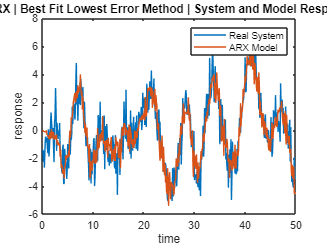


%%
figure(1)
plot(t,y_val,t,BestFit_y_hat)
legend('Real System','ARX Model')
title(" ARX | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

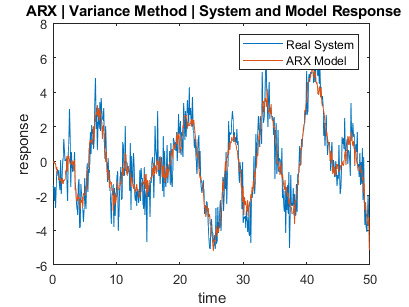


figure(2)
plot(t,y_val,t,Var_y_hat)
legend('Real System','ARX Model')
title(" ARX | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

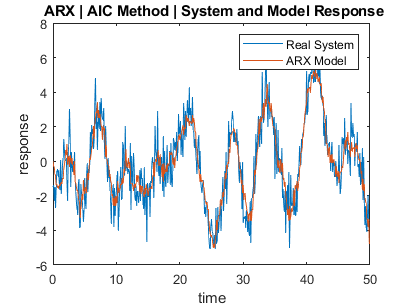


figure(3)
plot(t,y_val,t,AIC_y_hat)
legend('Real System','ARX Model')
title(" ARX | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

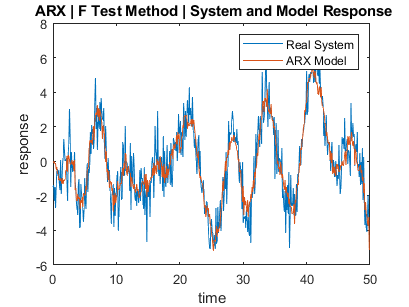


figure(4)
plot(t,y_val,t,FTest_y_hat)
legend('Real System','ARX Model')
title(" ARX | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

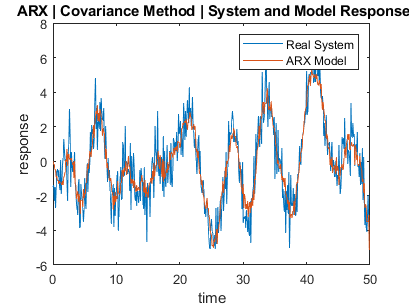


figure(7)
plot(t,y_val,t,Cov_y_hat)
legend('Real System','ARX Model')
title(" ARX | Covariance Method | System and Model Response")
xlabel("time")
ylabel("response")


%%

figure(5)
subplot(5,1,1)
plot(1:N-1,BestFit_Ree(2:end), 1:N-1, mean(BestFit_Ree(2:end))*ones(length(1:N-1)))
title(" ARX | Best Fit Lowest Errror Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(5,1,2)
plot(1:N-1,Var_Ree(2:end), 1:N-1, mean(Var_Ree(2:end))*ones(length(1:N-1)))
title(" ARX | Variance Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(5,1,3)
plot(1:N-1,AIC_Ree(2:end), 1:N-1, mean(AIC_Ree(2:end))*ones(length(1:N-1)))
title(" ARX | AIC Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(5,1,4)
plot(1:N-1,FTest_Ree(2:end), 1:N-1, mean(FTest_Ree(2:end))*ones(length(1:N-1)))
title(" ARX | F Test Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(5,1,5)
plot(1:N-1,Cov_Ree(2:end), 1:N-1, mean(Cov_Ree(2:end))*ones(length(1:N-1)))
title(" ARX | Covariance Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")


%%

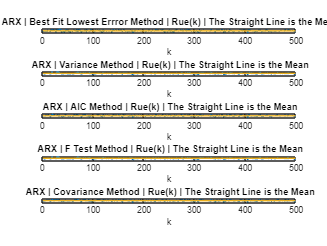


figure(6)
subplot(5,1,1)
plot(1:N-1,BestFit_Rue(2:end), 1:N-1, mean(BestFit_Rue(2:end))*ones(length(1:N-1)))
title(" ARX | Best Fit Lowest Errror Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(5,1,2)
plot(1:N-1,Var_Rue(2:end), 1:N-1, mean(Var_Rue(2:end))*ones(length(1:N-1)))
title(" ARX | Variance Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(5,1,3)
plot(1:N-1,AIC_Rue(2:end), 1:N-1, mean(AIC_Rue(2:end))*ones(length(1:N-1)))
title(" ARX | AIC Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(5,1,4)
plot(1:N-1,FTest_Rue(2:end), 1:N-1, mean(FTest_Rue(2:end))*ones(length(1:N-1)))
title(" ARX | F Test Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")


subplot(5,1,5)
plot(1:N-1,Cov_Rue(2:end), 1:N-1, mean(Cov_Rue(2:end))*ones(length(1:N-1)))
title(" ARX | Covariance Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")



%%